% Size of the board (e.g., 8x8)
N = 8;

% Create the checkerboard matrix
mask = subsample_mask(2)
board = ~reshape(mask(1:64), 8, []);

% Plot
clf
imagesc(board);
colormap(gray);      % Black and white colormap
axis equal tight;    % Square pixels, no borders
xticks([]); yticks([]); % Remove axis ticks

% Draw grid lines
hold on
for k = 0:N
    % Horizontal lines
    line([0, N] + 0.5, [k, k] + 0.5, 'Color', 'k');
    % Vertical lines
    line([k, k] + 0.5, [0, N] + 0.5, 'Color', 'k');
end
hold off

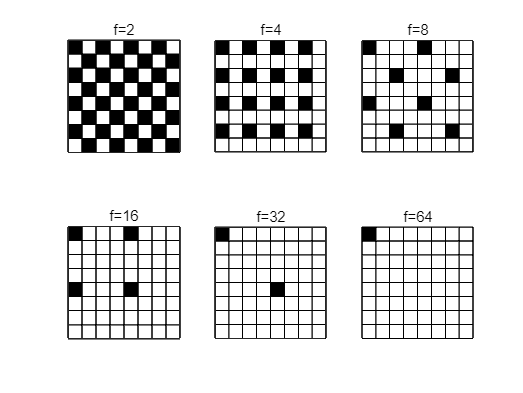

N = 8;

% Create a 2x3 grid
figure;
for i = 1:6
    f=2.^i;
    % Create the checkerboard matrix
    mask = subsample_mask(f);
    board = ~reshape(mask(1:64), 8, []);
    subplot(2,3,i);
    plot_board(board);
    subtitle(sprintf("f=%d", f));
end
axis off


% Function to plot a single board with grid

function plot_board(board)

    imagesc(board);
    colormap(gray);
    axis equal tight;
    xticks([]); yticks([]);
    hold on
    for k = 0:size(board,1)
        line([0, size(board,2)] + 0.5, [k, k] + 0.5, 'Color', 'k');
        line([k, k] + 0.5, [0, size(board,1)] + 0.5, 'Color', 'k');
    end
    hold off
end
